# Spectral decomposition

This Spectr-O-Matic example decomposes a mixture spectrum into reference components by linear least squares fit. 

## Load reference and mixture spectra

The file *mixturedata.mat* contains 2 variables:

- *A*   - 2 gaussian reference spectra 

- *B*   - a noisy spectrum of a 3:2 mixture of *A*: `B = 3*A1 + 2*A2`

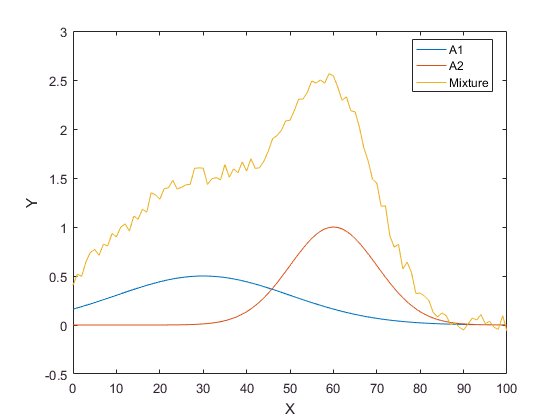

load mixturedata
figure; plot(A,B)

## Decompose mixture spectrum

Fit the spectrum B as a linear combination of the spectra in A.

c = A \ B;

- *c* - array of linear coefficients

disp(c)

    3.0106
    1.9932



## Inspect result

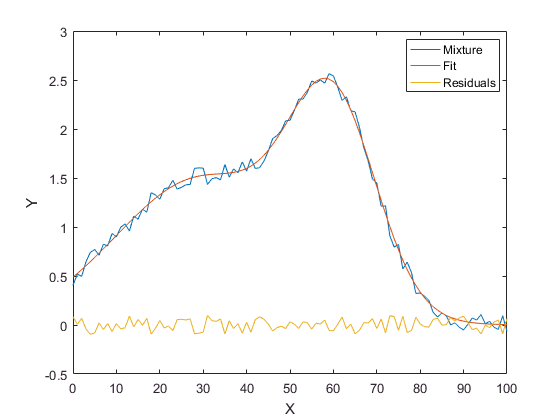

F = sum(A*c); F.ID = 'Fit';
R = F - B;    R.ID = 'Residuals';
figure; plot(B, F, R)